% ECE711 - Project
%!! RUN THİS FİRST !!


clc; clear;
% Intialization

Rr  =  1.39e-3;             % ohm, Rotor resistance
Rs  =  1.343e-3;            % ohm, Stator resistance
fb  =  50;                  % Hz, Base frequency
p   =  6;                   % Number of poles
M   =  6;                   % sec, mechanical time constant
Pb  =  1.45e6;              % W, base power
Ib  =  1723*sqrt(2);        % A, base current
we  =  2*pi*fb;             % erad/s, synchronous speed
wmb =  we*(2/p);            % mrad/s, mechanical base speed
Tb  =  13.944e3;            % Nm, rated torque
Vb  = 331.98*sqrt(2);       % V, supply phase peak voltage
J = p/2*Pb*M/(wmb^2);       % inertia


% Impedance and angular speed calculations
Lls     =  0.1044e-3;       % H, Stator inducatnce
Llr     =  0.0498e-3;       % H, Rotor inductance
Lm      =  1.77016e-3;      % H, Magnetizing Inductance 
Lr      = Llr + Lm;

Xls     =  Lls*we;          % Ohm, Stator impedance
Xlr     =  Llr*we;          % Ohm, Rotor impedance
Xm      =  Lm*we;           % Ohm, Magnetizing impedance
wb      =  2*pi*fb;         % rad/s, Base speed
Xmstar  =  1/(1/Xls+1/Xm+1/Xlr);


% part a condition
slip = 0.0177;
wrotor = wb*(1-slip);      % rad/s, Base speed
 
% initial flux voltages
% iqds0_e = (1.0343 - 0.5470i)*Ib;
% iqdr0_e = (-1.0660 + 0.2379i)*Ib;
% 
% iqs0 = real(iqds0_e);  ids0 = -imag(iqds0_e);
% iqr0 = real(iqdr0_e);  idr0 = -imag(iqdr0_e);

% fqs0 = Xls*iqs0 + Xm*(iqr0+iqs0)
% fds0 = Xls*ids0 + Xm*(idr0+ids0)
% fqr0 = Xlr*iqr0 + Xm*(iqs0+iqr0)
% fdr0 = Xlr*idr0 + Xm*(ids0+idr0)

% results obtained from ss operating from simulink
% fqs0 = 3.091496;
% fds0 = 370.160566;
% fqr0 = -76.149885;
% fdr0 = 340.507385;

fqs0 = 0;
fds0 = 0;
fqr0 = 0;
fdr0 = 0;


% Load Torque
Tload = linspace(-5*Tb, 5*Tb, 10);               % Nm, load torque
wr_table = zeros(1, length(Tload))

wr_table =      0     0     0     0     0     0     0     0     0     0


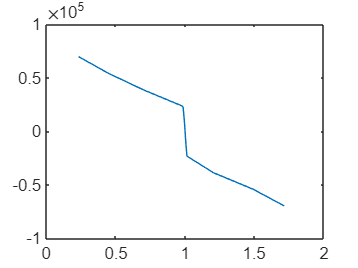

for j = 1:length(Tload)
    sim("Project", 3);
    wr_table(1,j) = outputVars(length(outputVars),1);
end
plot(wr_table, Tload)